#### Part 2: Tuning Fork

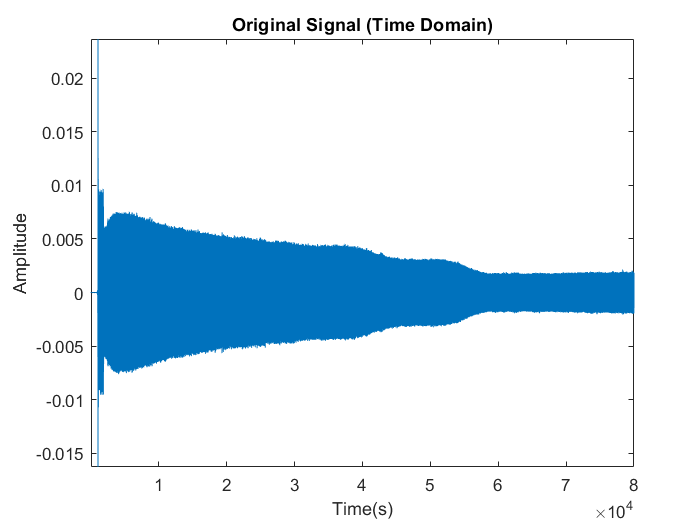

% Part 2.2: Analyze Audio Signal

load audioclip.mat;
N = 8000;

X_f = fft(audio, N)/N;
F = -Fs/2:Fs/N:(N-1)*Fs/(2*N);
X_f_db = 10*log(abs(X_f));
X_omg = fftshift(X_f_db);

figure
plot(audio), axis tight;
title('Original Signal (Time Domain)')
xlabel('Time(s)')
ylabel('Amplitude')

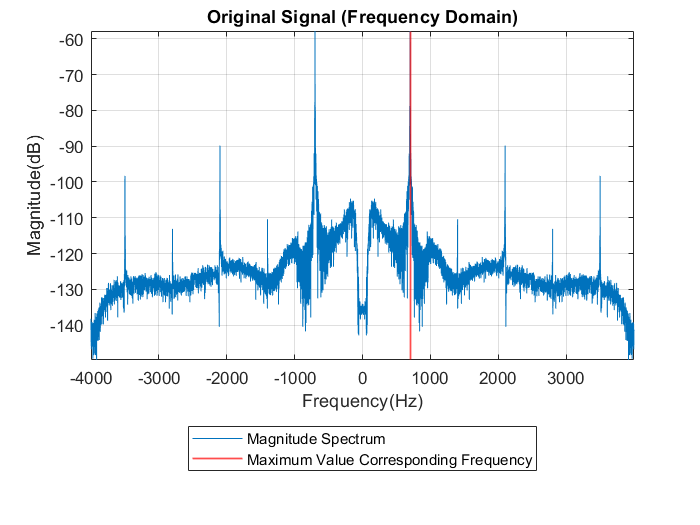


figure
plot(F, X_omg), axis tight;
title('Original Signal (Frequency Domain)')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')
xline(700, 'linewidth', 1, 'color', 'r');
legend("Magnitude Spectrum", "Maximum Value Corresponding Frequency", "Location","southoutside")
grid on

#### Part 3: Voice Pitch

%% Part 3.2: Voice Pitch Analyzer %%

clear variables
load voiceclip.mat;
N = 8000;

figure
voice_pitch = pitch(voice, Fs);
plot(voice_pitch), xlabel('Frame'), ylabel('Pitch'), grid on;
title("Pitch Plot of Voice Signal Throughout Audio");
hold on
avg_pitch = mean(voice_pitch)

avg_pitch = 132.9429

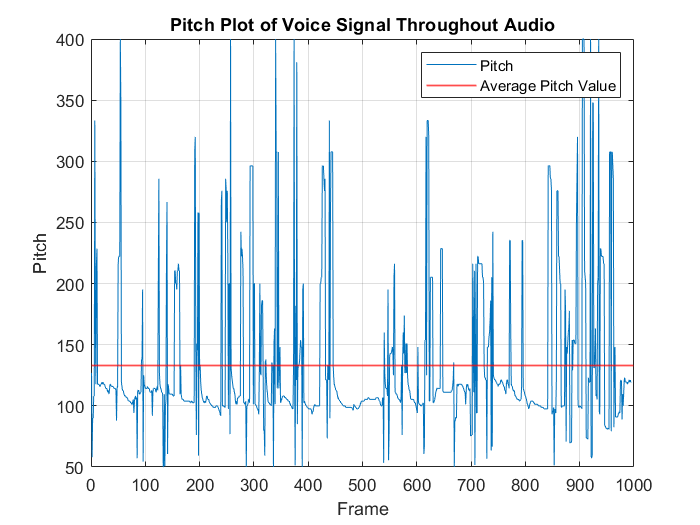

yline(avg_pitch, 'linewidth', 1, 'color', 'r');
legend("Pitch", "Average Pitch Value");


X_f = fft(voice, N)/N;
F = -Fs/2:Fs/N:(N-1)*Fs/(2*N);
X_f_db = 10*log(abs(X_f));
X_omg = fftshift(X_f_db);

figure
plot(F, X_omg), axis tight, grid minor, xlim([-1200, 1200]);
title('Magnitude Spectrum of Voice Signal')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')
[max index] = max(X_omg);
dominant_frequency = abs(F(index));
hold on

smoothdata = smoothdata(X_omg, "lowess");
% plot(F, smoothdata)
[peak_value index] = findpeaks(smoothdata);
numpeaks = size(peak_value, 1);
peak_index = ceil(numpeaks/2+1);
pitch_index = index(peak_index);
pitch_frequency = F(pitch_index)

pitch_frequency = 115

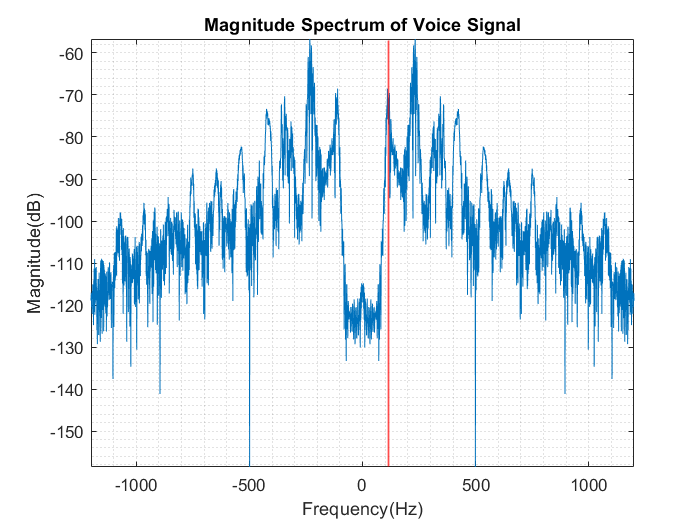

xline(pitch_frequency, 'linewidth', 1, 'color', 'r')

#### Part 4: Noisy Signal

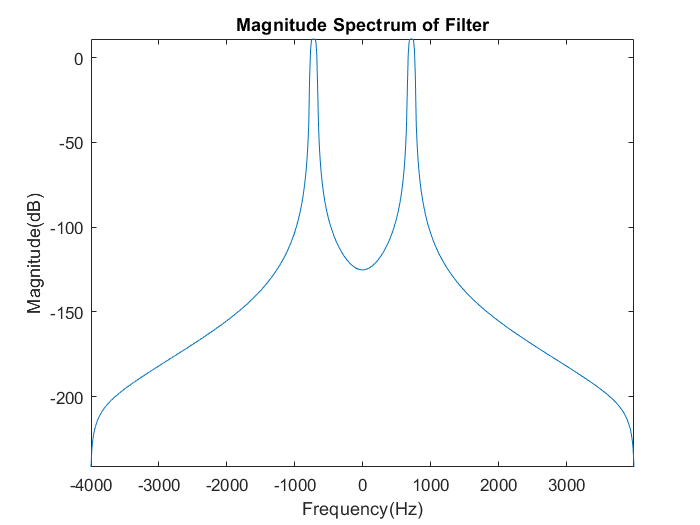

%% Part 4.1 Magnitude Spectrum of Noisy Signal %%

N = 5000;
Fs = 8000;
load audioclip.mat;
noise = audio + 0.01*randn(length(audio),1);
Xf_noise = fft(noise, N)/N;

X_f_noisy = fft(audio, N)/N;
F = -Fs/2:Fs/N:(N-1)*Fs/(2*N);

%% Part 4.2: Filter Design and Implementation %%

% Filter Design
Fc1=675; % cutoff freq 1
Fc2=765;
L=303; % number of coefficients, 91 || 171 work well
n=0:2*L;
attenuation_factor = 3;
h_w_1=2*Fc1/Fs*sinc(2*Fc1/Fs*(n-L)) * attenuation_factor;
h_w_2=2*Fc2/Fs*sinc(2*Fc2/Fs*(n-L)) * attenuation_factor;
hann_window = 1/2*(1-cos(2*pi*n/(2*L)));
h_hann_1 = h_w_1 .* hann_window;
h_hann_2 = h_w_2 .* hann_window;
h_LPF = h_hann_2 - h_hann_1;
H_LPF = fft(h_LPF);
F_filter = -Fs/2:Fs/length(H_LPF):(length(H_LPF)-1)*Fs/(2*length(H_LPF));

% Filter plot in Frequency Domain
figure
plot(F_filter, fftshift(10*log(abs(H_LPF)))), axis tight;
title('Magnitude Spectrum of Filter')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')

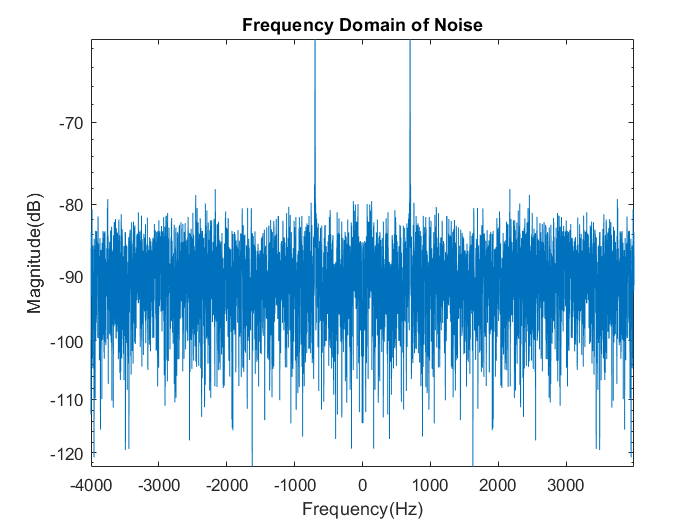


% Filtered Signal
filteredSignal = conv(h_LPF, noise);
filteredSignalTransform = fft(filteredSignal, N)/N;

% Plot of the noisy signal in frequency domain
figure
semilogy(F, fftshift(10*log(abs(Xf_noise)))), axis tight;
title('Frequency Domain of Noise')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')

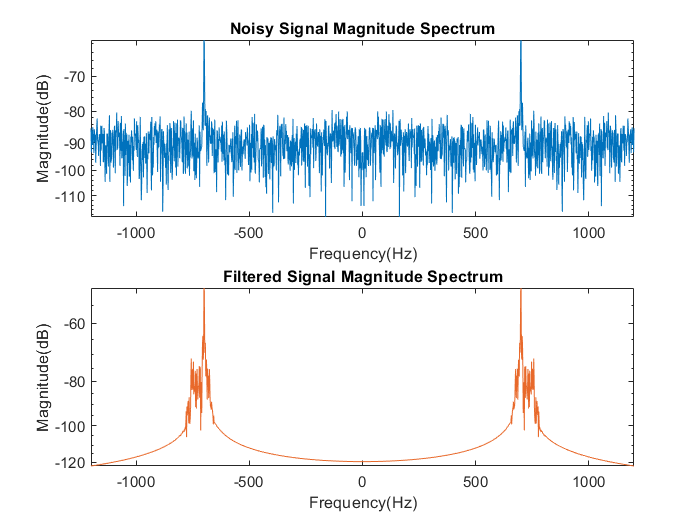


% Plot of original audio and filtered signal in freq. domain
figure
subplot(2, 1, 1)
semilogy(F, fftshift(10*log(abs(Xf_noise)))), axis tight, xlim([-1200, 1200]);
title('Noisy Signal Magnitude Spectrum')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')

subplot(2,1,2)
semilogy(F, fftshift(10*log(abs(filteredSignalTransform))),"Color", [0.9100    0.4100    0.1700])
title('Filtered Signal Magnitude Spectrum'), axis tight, xlim([-1200, 1200]);
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')

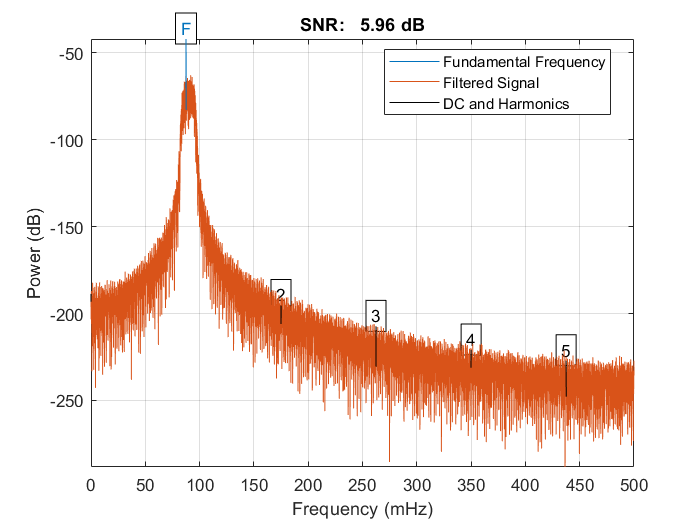

ans = 5.9592


% Computing signal to noise ratio
figure
snr(filteredSignal), axis tight, legend('Fundamental Frequency', 'Filtered Signal', 'DC and Harmonics');

#### Play Noise

clear sound
% sound(noise)

#### Play Filtered Audio

clear sound
% sound(filteredSignal)

#### Play Original Audio

clear sound
% sound(audio)